### La Quantizzazione del Colore

La quantizzazione è il processo di creare una **palette di colori ottimale** (es. 256 colori) per descrivere un'immagine.

L'algoitmo più famoso è quello del **Median-Cut. **

- Immagina tutti i colori presenti nell'immagine come punti in un grande cubo 3D (lo spazio colore RGB)

- Restringi questo cubo al minimo parallelepipedo che contiene tutti i pixel.

- Trova il lato più lungo di questo parallelepipedo (il canale R, G, o B con la maggiore differenza tra massimo e minimo).

- Ordina tutti i pixel lungo quel lato e dividi il parallelepipedo in due, tagliando nel punto mediano. Ora hai due "scatole".

- Ripeti questo processo sulle nuove scatole, scegliendo sempre quella con il volume maggiore, fino a quando non hai il numero di scatole (regioni) desiderato (es. 256).

- **Creazione Tavolozza:** Calcola il colore medio (baricentro) di tutti i pixel in ogni scatola. L'insieme di questi colori medi forma la tua nuova **colormap ottimale**.

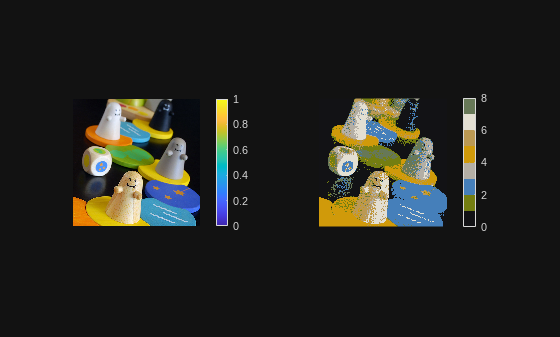

% la funzione rgb2ind implementa questo algoritmo in maniera efficiente.
img_rgb = imread("imgs/game.png");

% covertiamo l'immagine a 16 colori
[img_ind, map] = rgb2ind(img_rgb, 8);

% Visualizziamo l'immagine indicizzata
figure;subplot(1,2,1);imshow(img_rgb); colorbar;
subplot(1,2,2);imshow(img_ind, map); colorbar;

Possiamo fare la stessa cosa su un'immagine in scala di grigio 

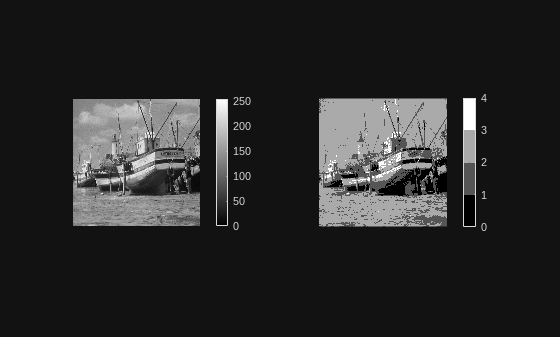

img_gray = imread("imgs/boat.png");

[img_ind_gray, map_gray] = gray2ind(img_gray,4);
figure;subplot(1,2,1);imshow(img_gray); colorbar;
subplot(1,2,2);imshow(img_ind_gray, map_gray); colorbar;

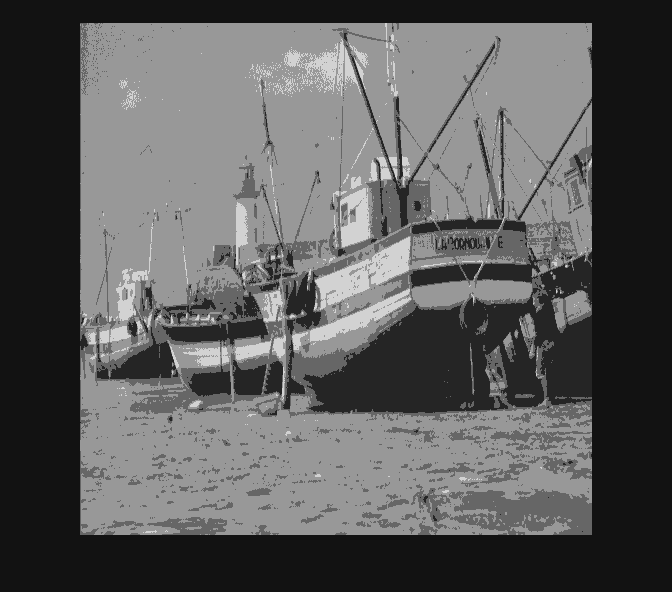

% Funzione di quantizzazione dei livelli di grigio.
function img = quantizza_media(img, numeroColori)

% Converti in gray-scale
if ndims(img) == 3
    img = single(rgb2gray(img));
end

% Calcolo degli estremi e del passo
min_val = min(img(:));
max_val = max(img(:));
passo = (max_val-min_val)/numeroColori;

% Applica la quantizzazione con media a tutti i bin tranne l'ultimo
for k = 0 : numeroColori - 2
    inf = round(min_val + k * passo);
    sup = round(min_val + (k+1) * passo);
    idx = img >= inf & img < sup;
    img(idx) = round(mean(img(idx)));
end

% Ultimo intervallo, include anche il valore massimo
inf = round(min_val + (numeroColori - 1) * passo);
idx = img >= inf & img <= max_val;
img(idx) = round(mean(img(idx)));

% Conversione finale a uint8 per visualizzazione
img = uint8(img);
end

% Applica la quantizzazione all'immagine indicizzata in scala di grigi
quantizedImg = quantizza_media(img_gray, 4);
figure; imshow(quantizedImg); 

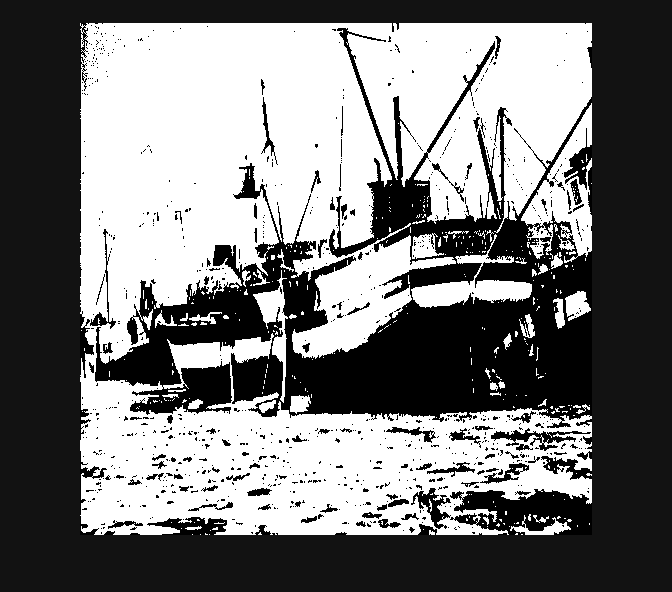

function img_out = quantizza_2colori(img)
    img = double(img);
    img_out = zeros(size(img));
    
    % Quantizzazione binaria semplice
    img_out(img >= 127) = 255;
    img_out(img < 127) = 0;
    
    img_out = uint8(img_out);
end

Img2c = quantizza_2colori(img_gray);
figure; imshow(Img2c); 

### Dithering

Il concetto chiave del dithering è la **diffusione dell'errore**. Non ci si limita a scegliere il colore/livello di grigio più vicino, ma calcoliamo l'errore commesso e lo "spalmiamo" sui pixel vicini che non abbiamo ancora elaborato. Questo inganna l'occhio, creando l'illusione di più colori o sfumatutre di quante ce ne siano in realtà. 

L'algoritmo di **Floyd-Steinberg** è il metodo di diffusione dell'errore più famoso.

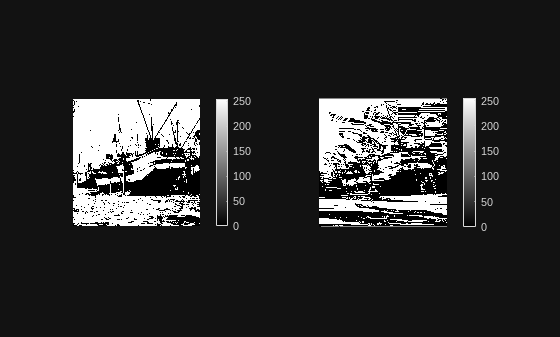

function out = FSDithering_2Colors(img)
[h, w] = size(img);
    img = double(img);

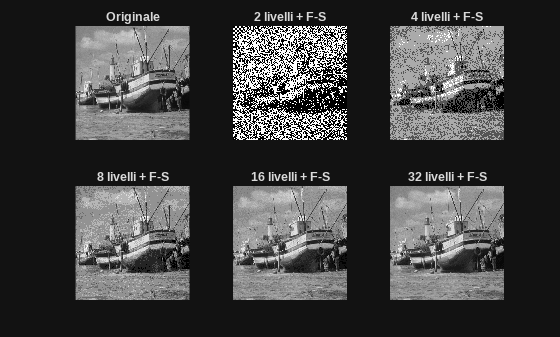

    out = double(img);

    for j = 1:h
        for i = 1:w
            % quantizzazione binaria personalizzata
           if out(j,i) >= 127
                out(j,i) = 255;
            else
                out(j,i) = 0;
           end

            % calcola errore rispetto all'immagine originale
            err = img(j,i) - out(j,i);

            % diffondi l'errore
            % Diffondi l'errore ai pixel vicini
            if i < w
                out(j,i+1) = out(j,i+1) + 7/16 * err;
            end
            
            if j < h && i > 1
                out(j+1,i-1) = out(j+1,i-1) + 3/16 * err;
            end
            
            if j < h
                out(j+1,i) = out(j+1,i) + 5/16 * err;
            end
            
            if i < w && j < h
                out(j+1,i+1) = out(j+1,i+1) + 1/16 * err;
            end
        end
    end
    out = uint8(out);
end

dithered_img = FSDithering_2Colors(img_gray);
figure;subplot(1,2,1);imshow(Img2c); colorbar;
subplot(1,2,2);imshow(dithered_img,[]); colorbar;
% Floyd-Steinberg per N livelli di grigio
function out = FSDithering_MultiLevel(img, num_livelli)
    [h, w] = size(img);
    img = double(img);
    out = img; % Copia dell'immagine originale
    
    % Definisci i livelli di quantizzazione (es. per 16 livelli)
    levels = linspace(0, 255, num_livelli);
    
    for j = 1:h
        for i = 1:w
            % Salva valore originale

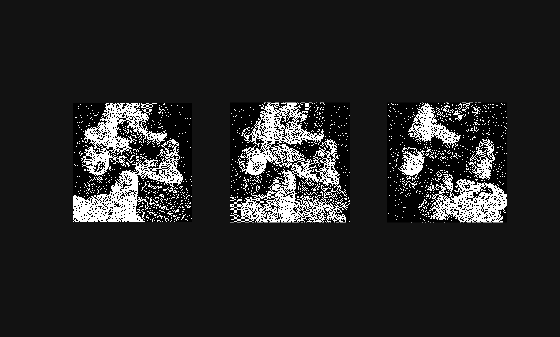

            pixel_orig = out(j,i);
            
            % Trova il livello più vicino
            [~, idx] = min(abs(levels - pixel_orig));
            out(j,i) = levels(idx);
            
            % Calcola errore
            err = pixel_orig - out(j,i);
            
            % Diffondi errore (stesso pattern Floyd-Steinberg)
            if i < w
                out(j,i+1) = out(j,i+1) + 7/16 * err;
            end
            if j < h && i > 1
                out(j+1,i-1) = out(j+1,i-1) + 3/16 * err;
            end
            if j < h
                out(j+1,i) = out(j+1,i) + 5/16 * err;

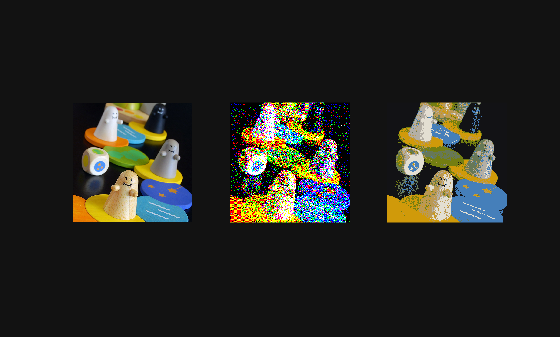

            end
            if i < w && j < h
                out(j+1,i+1) = out(j+1,i+1) + 1/16 * err;
            end

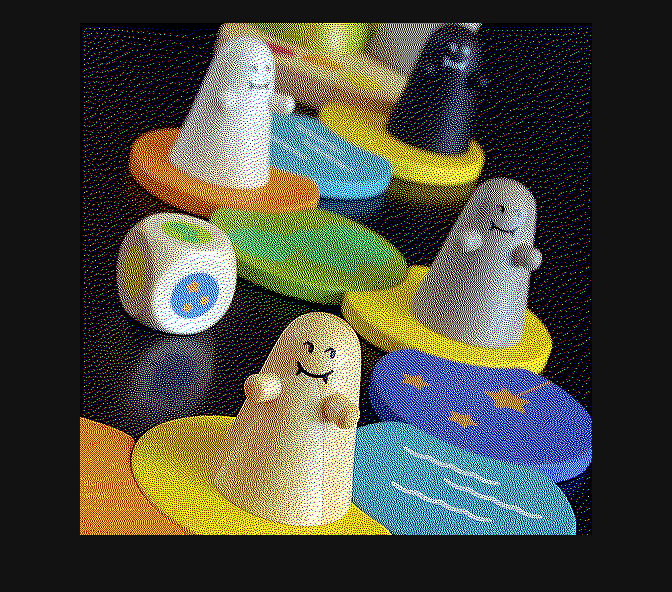

        end
    end

    out = uint8(out);
end

% Esempio di test con diversi livelli
figure;
subplot(2,3,1); imshow(img_gray); title('Originale');

% Prova con diversi numeri di livelli
for idx = 1:5
    n_levels = [2, 4, 8, 16, 32];
    subplot(2,3,idx+1);
    img_dith = FSDithering_MultiLevel(img_gray, n_levels(idx));
    imshow(img_dith);
    title(sprintf('%d livelli + F-S', n_levels(idx)));
end

### Dithering per immagini RGB

Il metodo più semplice è quello di applicare l'algoritmo già visto ai 3 canali RGB separatamente.

function out = FSDithering_RGB_Separate(img, colors)

    [h,w,c] = size(img);
    img = single(img);
    out = zeros(h,w,c);
    figure;
    for ch = 1:3
        out(:,:,ch) = FSDithering_MultiLevel(img(:,:,ch),colors);
        subplot(1,3,ch);imshow(out(:,:,ch));
    end
    
    out = uint8(out);

end

img_rgb_dith = FSDithering_RGB_Separate(img_rgb,2);
[img_ind, map] = rgb2ind(img_rgb, 8,"dither");
figure; subplot(1,3,1); imshow(img_rgb);
subplot(1,3,2); imshow(img_rgb_dith,[]);
subplot(1,3,3); imshow(img_ind,map);

figure; imshow(img_rgb_dith,[]);